# MECH 6323 - HW 07

Author: Jonas Wagner

Date: 2022-05-08

# Problem 1

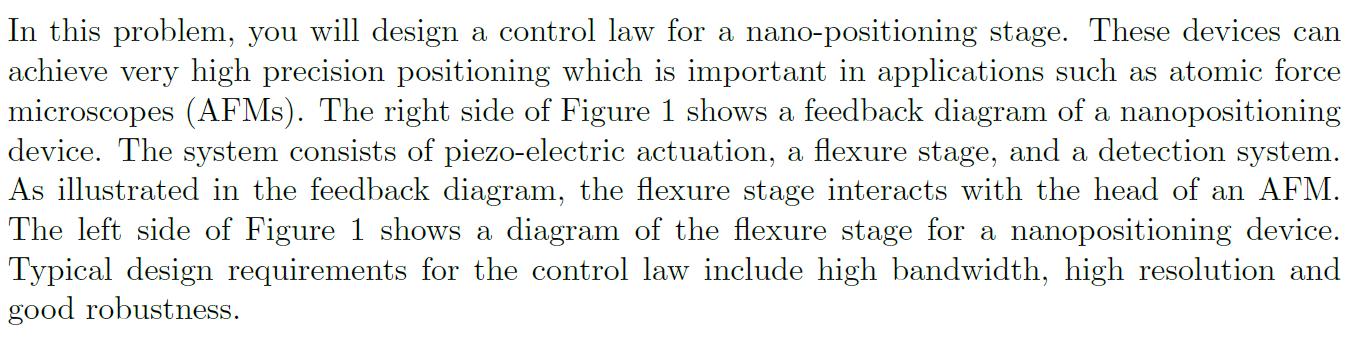

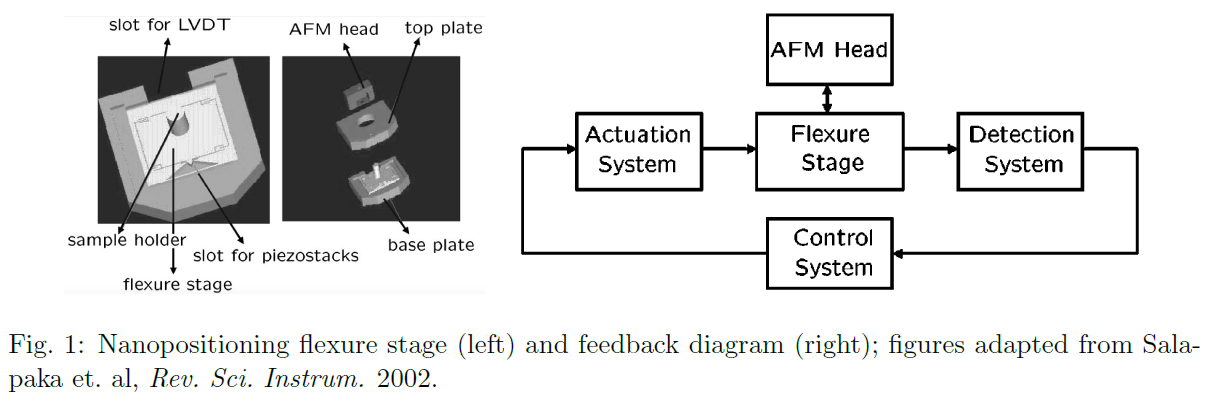

clear
close all

## Part a

nano_rsp = load('npresp.mat')

nano_rsp = struct with fields:
    Gfr: [1×1 frd]
      w: [1748×1 double]
      G: [1×1×1748 double]


omega_min = min(nano_rsp.w);
omega_max = max(nano_rsp.w);

#### Estimate system transfer function

tf_order = 6;
G_sys = fitfrd(nano_rsp.Gfr, tf_order)

G_sys =
 
  A = 
          x1     x2     x3     x4     x5     x6
   x1  -1468   8540  -8540   8540  -8540   4270
   x2  -4681   6559  -3757   3757  -3757   1878
   x3  -2174   4348  -7150   9952  -9952   4976
   x4  -4695   9390  -9390   6588  -3786   1893
   x5  -1687   3374  -3374   3374  -6176   4489
   x6  -3428   6856  -6856   6856  -6856  625.7
 
  B = 
          u1
   x1  5.156
   x2  11.36
   x3   16.7
   x4  18.15
   x5  11.59
   x6  11.18
 
  C = 
           x1      x2      x3      x4      x5      x6
   y1   114.1  -228.1   228.1  -228.1   228.1  -114.1
 
  D = 
            u1
   y1  0.08876
 
Continuous-time state-space model.



G_sys_tf = tf(G_sys)

G_sys_tf =
 
  0.08876 s^6 - 876.1 s^5 + 1.136e07 s^4 - 4.345e10 s^3 + 4.097e14 s^2 - 2.095e17 s + 3.082e21
  --------------------------------------------------------------------------------------------
       s^6 + 1021 s^5 + 7.856e07 s^4 + 5.129e10 s^3 + 1.342e15 s^2 + 3.65e17 s + 5.421e21
 
Continuous-time transfer function.



G_sys_zpk = zpk(G_sys)

G_sys_zpk =
 
  0.088762 (s^2 + 526.7s + 9.417e06) (s^2 + 276.6s + 4.494e07) (s^2 - 1.067e04s + 8.207e07)
  -----------------------------------------------------------------------------------------
         (s^2 + 186.2s + 6.029e06) (s^2 + 482.7s + 1.6e07) (s^2 + 352.5s + 5.621e07)
 
Continuous-time zero/pole/gain model.



#### Bode Diagram Data

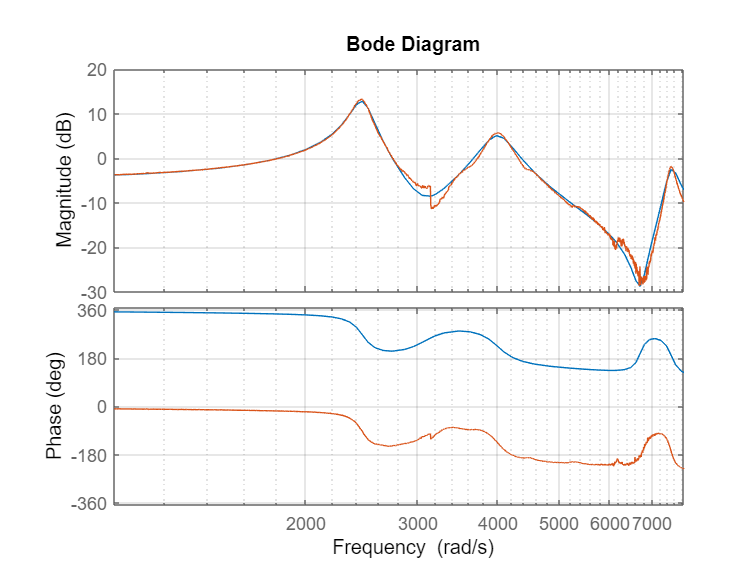

figure()
bode(G_sys)
hold on
bode(nano_rsp.Gfr)
grid on
xlim([omega_min, omega_max])

Clearly this plot is a good estimation for the frequency response of the system, noting that the phase of the system is offset by a 360 degree phase shift (which implies a need for another set of integrators)

## Part b 

### PI - Implimentation

PM_min = 75;
opt = pidtuneOptions( ...
    'PhaseMargin', PM_min, ...
    'DesignFocus', 'disturbance-rejection' ...
    )

opt =   pidtune with properties:

         PhaseMargin: 75
    NumUnstablePoles: 0
         DesignFocus: 'disturbance-rejection'


[C_pi, info] = pidtune(G_sys, 'pi', opt)

C_pi =
 
        1 
  Ki * ---
        s 

  with Ki = 240
 
Continuous-time I-only controller.



info = struct with fields:
                Stable: 1
    CrossoverFrequency: 136.5946
           PhaseMargin: 88.9408


allmargin(C_pi * G_sys)

ans = struct with fields:
     GainMargin: [2.3213 31.8215 13.3190]
    GMFrequency: [2.4472e+03 3.2556e+03 3.7346e+03]
    PhaseMargin: 88.9408
    PMFrequency: 136.5946
    DelayMargin: 0.0114
    DMFrequency: 136.5946
         Stable: 1


#### Bode Diagram of Margin

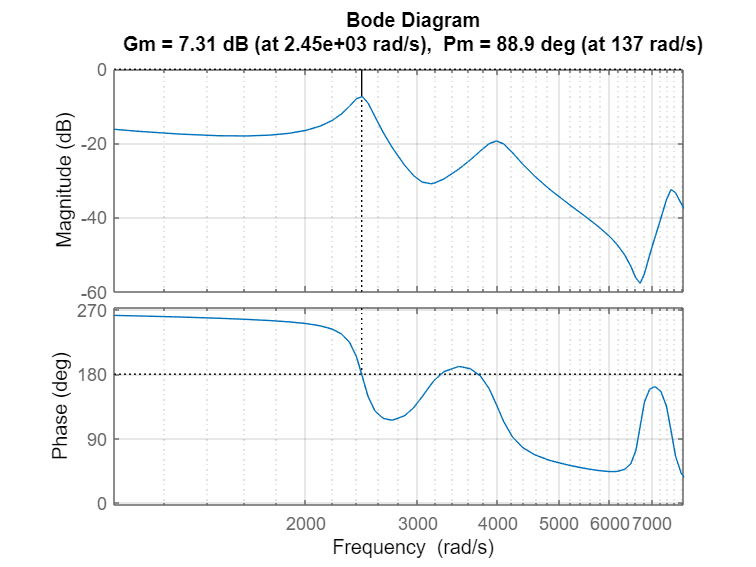

figure
margin(C_pi * G_sys_tf)
xlim([omega_min, omega_max])
grid on

As a result, the single only integral controller is a pretty weird result. However, looking at the results it does make sense.

#### Sensivity Transfer Function

S_pi = zpk(1/(1+C_pi*G_sys))

S_pi =
 
       s (s^2 + 186.2s + 6.029e06) (s^2 + 482.7s + 1.6e07) (s^2 + 352.5s + 5.621e07)
  ---------------------------------------------------------------------------------------
  (s+138.6) (s^2 + 108.1s + 5.995e06) (s^2 + 446.2s + 1.584e07) (s^2 + 349.8s + 5.615e07)
 
Continuous-time zero/pole/gain model.



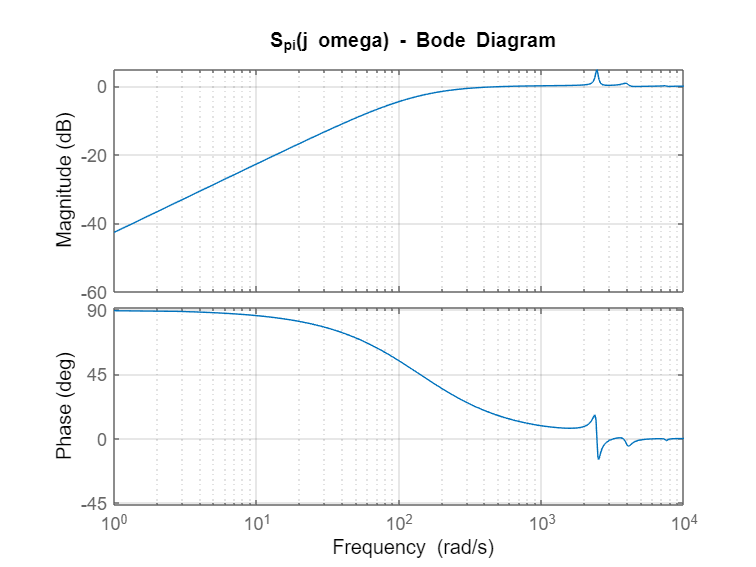

figure
bode(S_pi)
title('S_{pi}(j omega) - Bode Diagram')
grid on

#### Complimentary Transfer Function

T_pi = zpk(1/(1+C_pi*G_sys))

T_pi =
 
       s (s^2 + 186.2s + 6.029e06) (s^2 + 482.7s + 1.6e07) (s^2 + 352.5s + 5.621e07)
  ---------------------------------------------------------------------------------------
  (s+138.6) (s^2 + 108.1s + 5.995e06) (s^2 + 446.2s + 1.584e07) (s^2 + 349.8s + 5.615e07)
 
Continuous-time zero/pole/gain model.



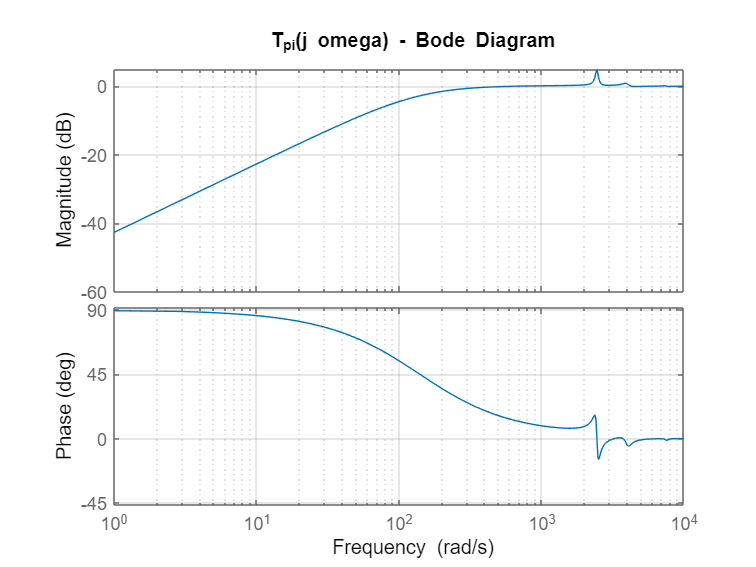

figure
bode(T_pi)
title('T_{pi}(j omega) - Bode Diagram')
grid on

#### Bandwith Calculation

bw_threshold = -3; %db
bw = getGainCrossover(S_pi, db2mag(bw_threshold))

bw = 134.4361

## Double Integrator implimenation

Instead we can also include an additional integrator into the controller, i.e.

G_int = tf(1,[1, 0]);
[C_pi_int, info] = pidtune(G_int * G_sys, 'pi', opt)

C_pi_int =
 
             1 
  Kp + Ki * ---
             s 

  with Kp = 271, Ki = 1.06e+04
 
Continuous-time PI controller in parallel form.



info = struct with fields:
                Stable: 1
    CrossoverFrequency: 159.0729
           PhaseMargin: 75.0000


allmargin(C_pi_int * G_int * G_sys)

ans = struct with fields:
     GainMargin: [0 2.0518 27.8933 11.9425]
    GMFrequency: [0 2.4457e+03 3.2626e+03 3.7282e+03]
    PhaseMargin: 75.0002
    PMFrequency: 159.0759
    DelayMargin: 0.0082
    DMFrequency: 159.0759
         Stable: 1


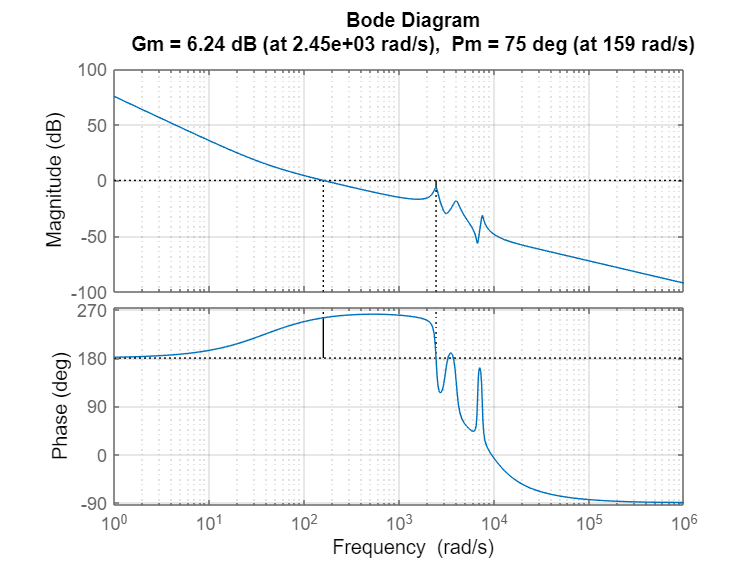

figure
margin(C_pi_int * G_int * G_sys)
grid on

#### Sensivity Transfer Function

S_pi_int = zpk(1/(1+C_pi_int*G_int*G_sys))

S_pi_int =
 
            s^2 (s^2 + 186.2s + 6.029e06) (s^2 + 482.7s + 1.6e07) (s^2 + 352.5s + 5.621e07)
  ---------------------------------------------------------------------------------------------------
  (s^2 + 156.3s + 6120) (s^2 + 97.81s + 5.989e06) (s^2 + 441.9s + 1.582e07) (s^2 + 349.5s + 5.614e07)
 
Continuous-time zero/pole/gain model.



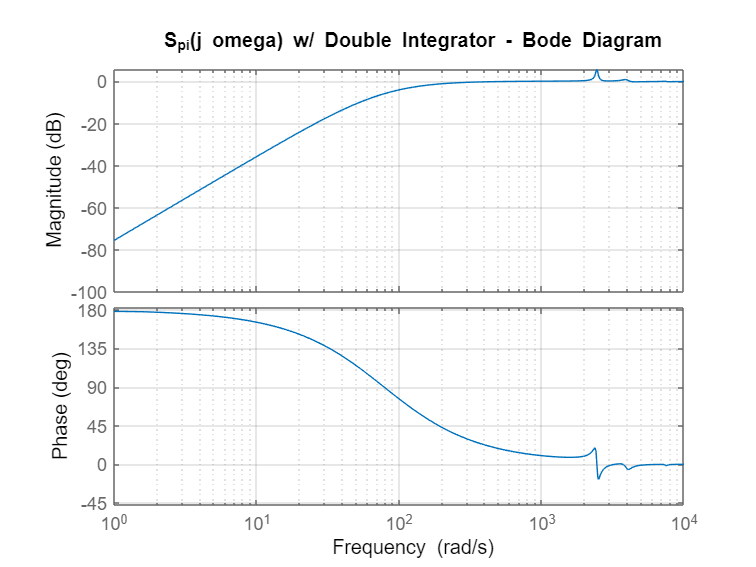

figure
bode(S_pi_int)
title('S_{pi}(j omega) w/ Double Integrator - Bode Diagram')
grid on

#### Complimentary Transfer Function

T_pi_int = zpk(1/(1+C_pi_int*G_int*G_sys))

T_pi_int =
 
            s^2 (s^2 + 186.2s + 6.029e06) (s^2 + 482.7s + 1.6e07) (s^2 + 352.5s + 5.621e07)
  ---------------------------------------------------------------------------------------------------
  (s^2 + 156.3s + 6120) (s^2 + 97.81s + 5.989e06) (s^2 + 441.9s + 1.582e07) (s^2 + 349.5s + 5.614e07)
 
Continuous-time zero/pole/gain model.



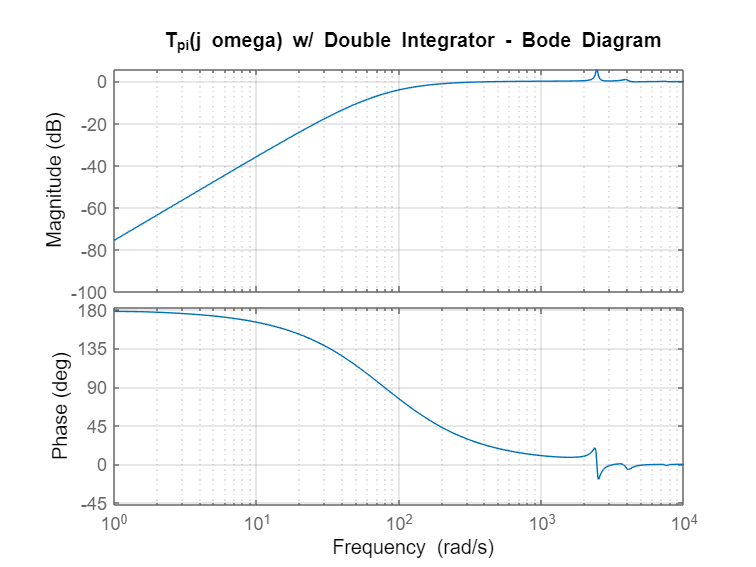

figure
bode(T_pi_int)
title('T_{pi}(j omega) w/ Double Integrator - Bode Diagram')
grid on

#### Bandwith Calculation

bw_threshold = -3; %db
bw = getGainCrossover(S_pi_int, db2mag(bw_threshold))

bw = 117.7945

The bandwidth of this method is not as great as the original PI implimenation. I think the performance is better in certain situation though and may be worth implimenting (even if it isn't really a PI controller)

## Part c

### Specs:

- Bandwidth ($|S(j\omega)| = -3$ dB) is around 250 Hz

- 
$$|S(j\omega)| \leq 1.5 \ \forall_{\omega}$$


- Slope below bandwidth = 20 dB/decade

- DC gain of $S\leq -80$dB

- $|T(j\omega)| < -3$dB @ 500 Hz

- 
$$|T(j\omega)| \leq 1.5 \ \forall_\omega$$


- $|T(j\omega)| < -40$dB as $\omega \to \infty$

- 
$$|C_\infty S(j\omega)| \leq 10 \ \forall_{\omega}$$


### Design Weights

In order design using the mixed sensitivity design approach, we shape $S_{pi}(s)$ and $T_{pi}(s)$ to achieve the desired performance and robustness specs using weighting functions that are inverse of thoose desired shapes.

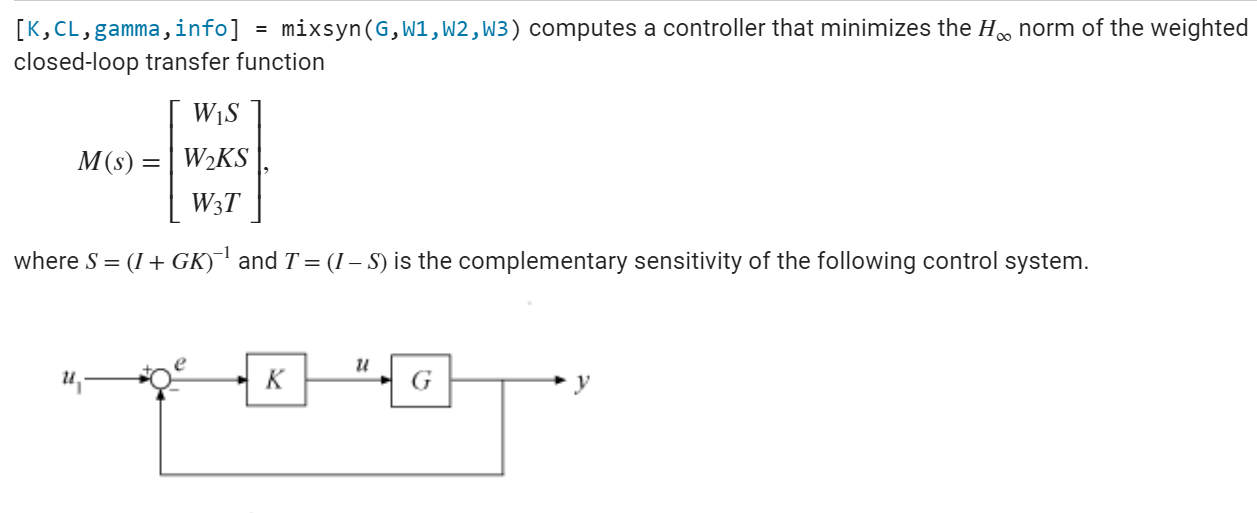

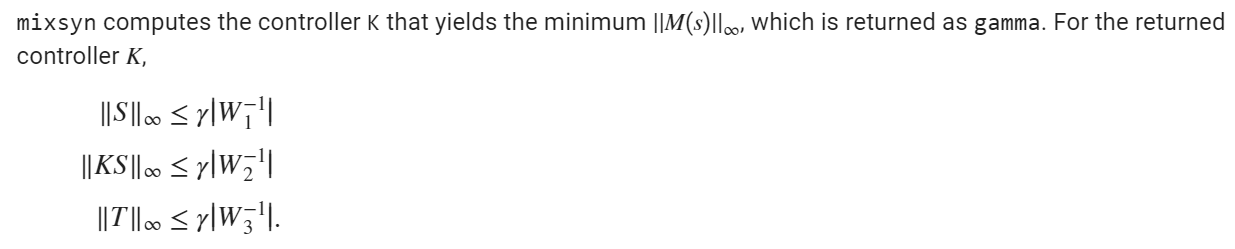

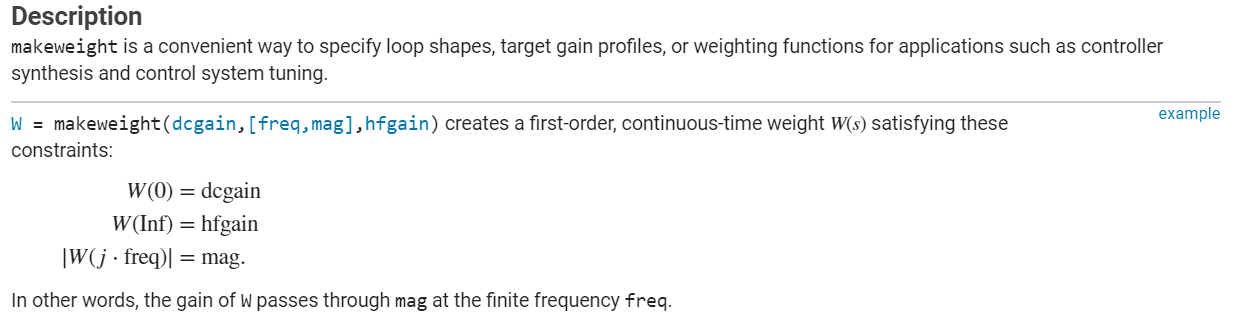

#### $W_1$ - Shaping $S$:        $||S||_\infty \leq \gamma |W^{-1}_1|$

dcgain_1 = db2mag(-80);% Spec 4
hfgain_1 = 1.5; % Spec 2
bw_1 = 250; % Spec 1
W_1 = makeweight(dcgain_1, [2*pi*bw_1, db2mag(-3)], hfgain_1)

W_1 =
 
  A = 
          x1
   x1  -2934
 
  B = 
       u1
   x1  64
 
  C = 
           x1
   y1  -68.77
 
  D = 
        u1
   y1  1.5
 
Continuous-time state-space model.



#### $W_2$ - Shaping $KS$:        $||KS||_\infty \leq \gamma |W^{-1}_2|$

u_max = 10;
W_2 = tf(1/u_max)

W_2 =
 
  0.1
 
Static gain.



#### $W_3$ - Shaping $T$:        $||T||_\infty \leq \gamma |W^{-1}_3|$

dcgain_3 = 1.5; % Spec 6 (max KS should be less then 1.5)
hfgain_3 = db2mag(-40); % Spec 7
bw_3 = 450; %should be less then 500 to ensure below -3dB @ 500 Hz
W_3 = makeweight(dcgain_3, [2*pi*bw_3, db2mag(-3)], hfgain_3)

W_3 =
 
  A = 
          x1
   x1  -1513
 
  B = 
       u1
   x1  64
 
  C = 
          x1
   y1  35.24
 
  D = 
         u1
   y1  0.01
 
Continuous-time state-space model.



### Plotting Weighting functions

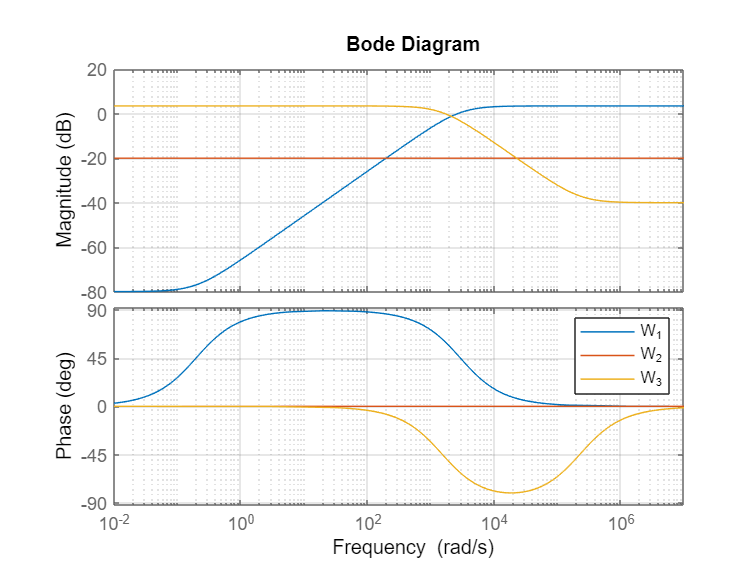

figure
hold on
bode(W_1)
bode(W_2)
bode(W_3)
legend('W_1','W_2','W_3')
grid on

### $H_\infty$controller Calculation

[C_Hinf,CL,gamma,info] = mixsyn(G_sys,W_1,W_2,W_3)

C_Hinf =
 
  A = 
               x1          x2          x3          x4          x5          x6          x7          x8
   x1       -2934   -1.51e-10   2.547e-11   4.657e-10  -9.313e-10   6.985e-10  -1.164e-10   8.731e-11
   x2   9.353e+04  -1.527e+04  -5.738e+04  -3.866e+06   4.894e+06  -4.182e+06   2.764e+06  -6.636e+05
   x3   8.488e+04  -1.249e+04  -6.017e+04  -3.487e+06    4.42e+06  -3.774e+06   2.486e+06  -5.914e+05
   x4   1.871e+05  -2.752e+04   -1.34e+05  -7.697e+06   9.756e+06  -8.331e+06   5.494e+06  -1.311e+06
   x5    2.75e+05  -4.046e+04  -1.924e+05  -1.132e+07   1.434e+07  -1.224e+07   8.074e+06  -1.925e+06
   x6   2.989e+05  -4.397e+04  -2.114e+05   -1.23e+07   1.558e+07  -1.331e+07   8.781e+06  -2.095e+06
   x7   1.908e+05  -2.807e+04  -1.336e+05  -7.853e+06    9.95e+06  -8.497e+06   5.601e+06  -1.334e+06
   x8   1.841e+05  -2.709e+04  -1.308e+05  -7.576e+06     9.6e+06  -8.198e+06   5.405e+06  -1.291e+06
 
  B = 
          u1
   x1     64
   x2  113.4
   x3    103
   

gamma = 1.4549

info =   hinfINFO with properties:

    gamma: 1.4549
        X: [8×8 double]
        Y: [8×8 double]
       Ku: [-325.4596 42.8192 1.8687e+03 9.4406e+03 -1.4372e+04 1.3922e+04 -1.0845e+04 3.5761e+03]
       Kw: [-869.6446 127.2423 943.6919 3.5037e+04 -4.4783e+04 3.8441e+04 -2.5510e+04 6.1675e+03]
       Lx: [8×1 double]
       Lu: 7.2026
     Preg: [5×2 ss]
       AS: [2×2 ss]


## Part d

### $H_\infty$-controller Margin Calculations

allmargin(C_Hinf*G_sys)

ans = struct with fields:
     GainMargin: 6.5542
    GMFrequency: 4.2065e+03
    PhaseMargin: [53.6057 -125.7859]
    PMFrequency: [1.2243e+03 1.6588e+06]
    DelayMargin: [7.6422e-04 2.4644e-06 0]
    DMFrequency: [1.2243e+03 1.6588e+06 Inf]
         Stable: 1


figure
margin(C_Hinf * G_sys)
grid on

### $PI$- vs $H_\infty$- controller Bode Comparrision

figure
hold on
bode(C_pi)
bode(C_Hinf)
legend('C_{pi}', 'C_{H_\infty}')
grid on

### Loop Transfer Functions

sys_pi = feedback(C_pi * G_sys, 1);
sys_Hinf = feedback(C_Hinf * G_sys, 1);

#### Bode Open Loop

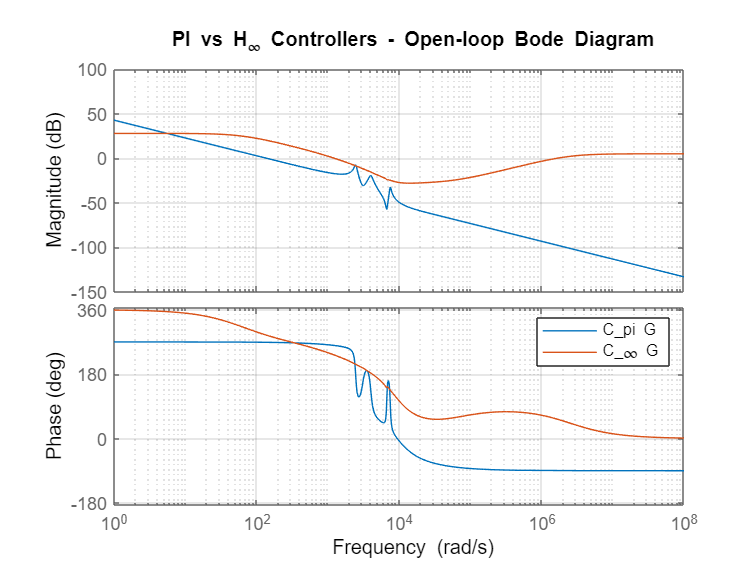

figure
hold on
bode(C_pi * G_sys, C_Hinf * G_sys)
legend('C_{pi} G', 'C_\infty G')
title('PI vs H_\infty Controllers - Open-loop Bode Diagram')
grid on

#### Bode Closed Loop

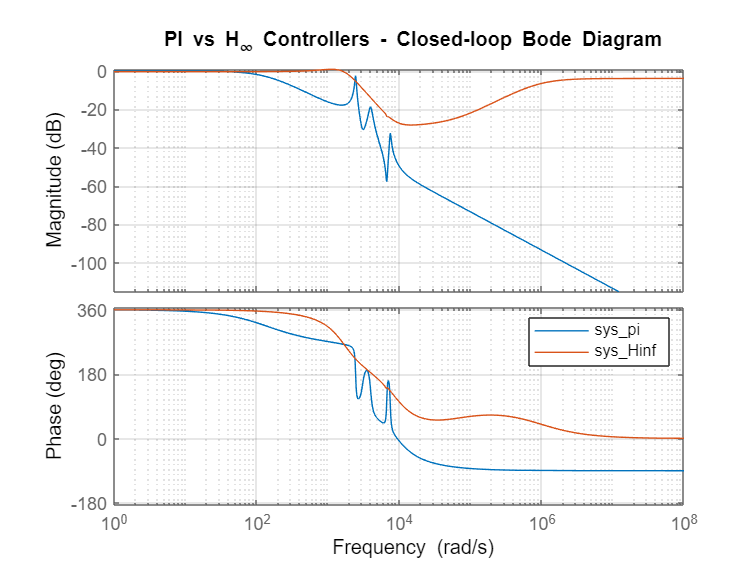

figure
hold on
bode(sys_pi,sys_Hinf)
legend
title('PI vs H_\infty Controllers - Closed-loop Bode Diagram')
grid on

#### Nyquist Loops

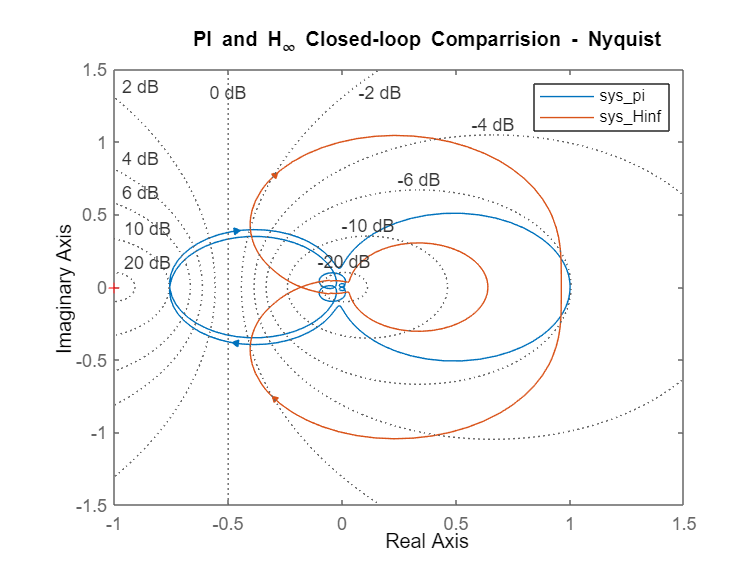

figure
nyquist(sys_pi, sys_Hinf)
legend
title('PI and H_\infty Closed-loop Comparrision - Nyquist')
grid on

# Problem 2

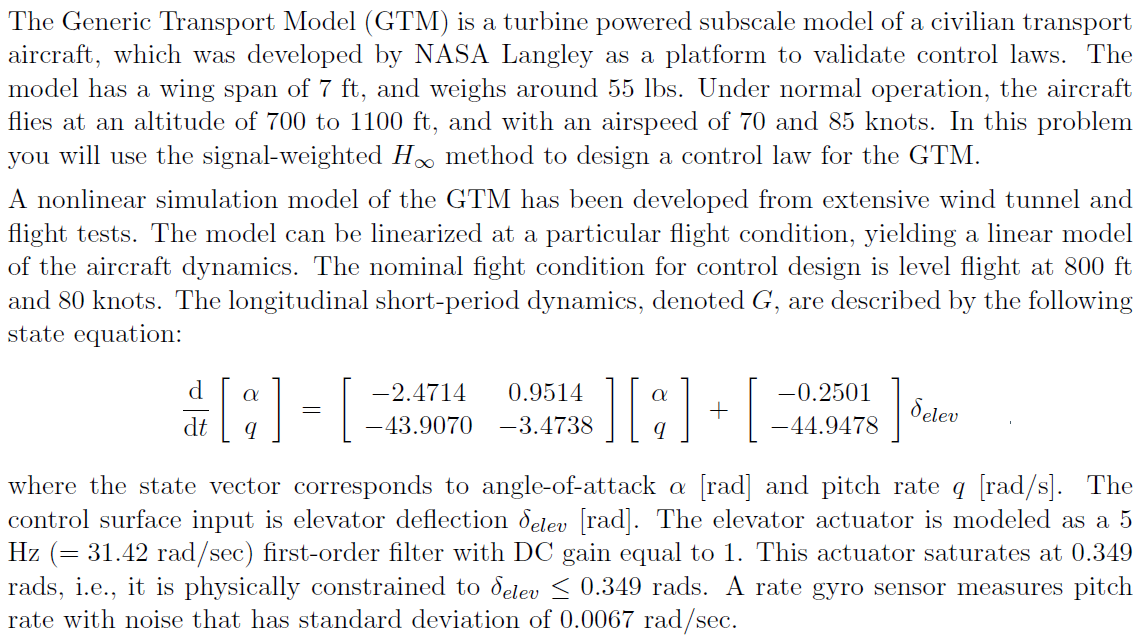

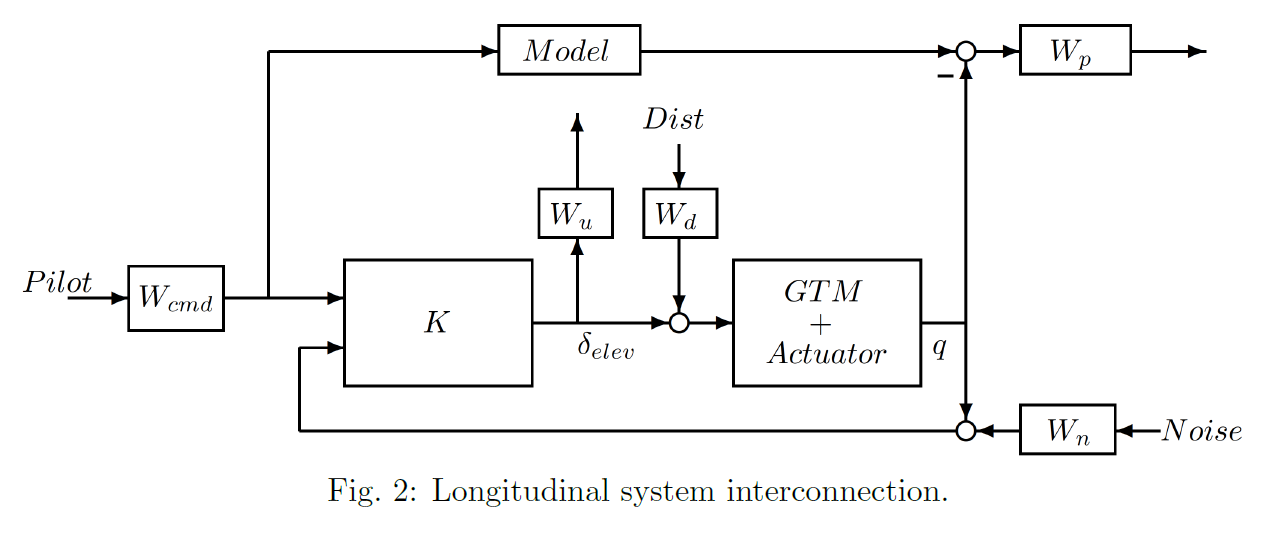

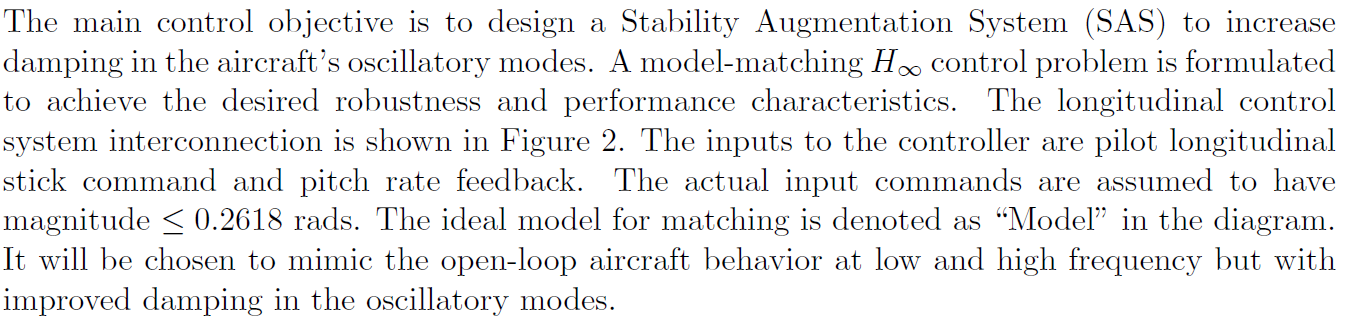

clear
close all

## Model Definition

#### Plant Definition

A = [
    - 2.4714     0.9514
    -43.9070    -3.4738
];
B = [
    - 0.2501
    -44.9478
];
C = [0 1];
D = 0;
G = ss(A,B,C,D);
G.InputName = 'delta_elev_act';
G.StateName = {'alpha', 'q'};
G.OutputName = {'q'}

G =
 
  A = 
           alpha       q
   alpha  -2.471  0.9514
   q      -43.91  -3.474
 
  B = 
          delta_elev_a
   alpha       -0.2501
   q            -44.95
 
  C = 
      alpha      q
   q      0      1
 
  D = 
      delta_elev_a
   q             0
 
Continuous-time state-space model.



#### Actuator Defintion

First order Actuator filter

p_act = 5 * 2 * pi;
k_act = 1;
G_act = tf(k_act * p_act, [1 p_act]);
G_act.InputName = 'delta_elev_sum';
G_act.OutputName = 'delta_elev_act'

G_act =
 
  From input "delta_elev_sum" to output "delta_elev_act":
    31.42
  ---------
  s + 31.42
 
Continuous-time transfer function.



#### Saturation?

Note: idk how to actually impliment a nonlinearirty within this type of a system... so idk, do we just want another crazy filter going to zero at 0.349 somehow? idk, why aren't we using Simulink since it would be way easier (even if we did it via code...)

#### Rate Gyro Sensor Error

Just a change in standard diveation from 1 to 0.0067...

std_gyro = 0.0067;
W_n = tf(std_gyro);
W_n.InputName = 'Noise';
W_n.OutputName = 'q_noise'

W_n =
 
  From input "Noise" to output "q_noise":
  0.0067
 
Static gain.



## Part a

[num_G, den_G] = tfdata(G)

num_G = 1×1 cell array
    {[0 -44.9478 -100.1029]}


den_G = 1×1 cell array
    {[1 5.9452 50.3583]}


[wn_G, zeta_G, p_G] = damp(G)

wn_G =     7.0964
    7.0964


zeta_G =     0.4189
    0.4189


p_G =   -2.9726 + 6.4438i
  -2.9726 - 6.4438i


zeta_damp = 0.8;
num_damp = num_G;
den_damp = den_G;
den_damp{1}(2) = den_G{1}(2) * (zeta_damp / zeta_G(1))

den_damp = 1×1 cell array
    {[1 11.3542 50.3583]}


G_damp = tf(num_damp, den_damp);
G_damp.InputName = 'Wcmd';
G_damp.OutputName = 'q_ideal'

G_damp =
 
  From input "Wcmd" to output "q_ideal":
    -44.95 s - 100.1
  ---------------------
  s^2 + 11.35 s + 50.36
 
Continuous-time transfer function.



[wn_G_damp, zeta_G_damp, p_G_damp] = damp(G_damp)

wn_G_damp =     7.0964
    7.0964


zeta_G_damp =     0.8000
    0.8000


p_G_damp =   -5.6771 + 4.2578i
  -5.6771 - 4.2578i


### Part b

$W_n$ - Gyro measurment error std

W_n % Gyro std from above

W_n =
 
  From input "Noise" to output "q_noise":
  0.0067
 
Static gain.



$W_u$ - Output to a normalized 

W_u = tf(1/0.349); % delta_elev normalized from delta_elev = [-0.349,0.349] to W_cmd = [-1,1]
W_u.InputName = 'delta_elev';
W_u.OutputName = 'Wu'

W_u =
 
  From input "delta_elev" to output "Wu":
  2.865
 
Static gain.



$W_{cmd}$ - Pilot comand input to setpoint

W_cmd = tf(0.2618); % Input normalized from Pilot = [-1,1] to W_cmd = [-0.2618,0.2618]
W_cmd.InputName = 'Pilot';
W_cmd.OutputName = 'Wcmd'

W_cmd =
 
  From input "Pilot" to output "Wcmd":
  0.2618
 
Static gain.



$W_p$ - Plant error output

error_max = 0.01;
W_p = tf(1/error_max); % Normalize from q = [-0.01,0.01] to W_p = [-1,1]
W_p.InputName = 'e';
W_p.OutputName = 'Wp'

W_p =
 
  From input "e" to output "Wp":
  100
 
Static gain.



$W_d$ - Disturbance Input

delta_limit = 0.349;
W_d_max = 0.15;
W_d = tf(delta_limit * W_d_max); % Gussing the Input normalized from u = [-1,1] to W_d = 0.15 * [-0.349,0.349] (15% 0f actuator limits)
W_d.InputName = 'Dist';
W_d.OutputName = 'delta_elev_dist'

W_d =
 
  From input "Dist" to output "delta_elev_dist":
  0.05235
 
Static gain.



### Part c

Although... I'm not sure why we are using connect (or even more outdated syssic) and all of this outdated structuring method instead of just setting this up and implimenting it within Simulink

#### Model Definition

Model = G_act * G_damp;
Model.InputName = 'Wcmd';
Model.OutputName = 'q_ideal';

#### Connect Definition

inputvar = {'Pilot', 'Dist', 'Noise', 'delta_elev'};
outputvar = {'Wp', 'Wu', 'Wcmd', 'q_sensor'};
APs = {'q'};

e_sum = sumblk('e = q_ideal - q');
q_sum = sumblk('q_sensor = q + q_noise');
delta_sum = sumblk('delta_elev_sum = delta_elev + delta_elev_dist');
P = connect( ...
    G, G_act, Model, W_n, W_d, W_p, W_u, W_cmd,...
    e_sum, q_sum, delta_sum,...
    inputvar, outputvar)

P =
 
  A = 
           alpha       q       ?       ?       ?       ?
   alpha  -2.471  0.9514  -1.964       0       0       0
   q      -43.91  -3.474    -353       0       0       0
   ?           0       0  -31.42       0       0       0
   ?           0       0       0  -42.77  -25.44  -12.36
   ?           0       0       0      16       0       0
   ?           0       0       0       0       8       0
 
  B = 
               Pilot        Dist       Noise  delta_elev
   alpha           0           0           0           0
   q               0           0           0           0
   ?               0      0.2094           0           4
   ?           2.094           0           0           0
   ?               0           0           0           0
   ?               0           0           0           0
 
  C = 
              alpha       q       ?       ?       ?       ?
   Wp             0    -100       0       0   -1103  -307.1
   Wu             0       0       0       0       0

Gs = tf(P)

Gs =
 
  From input "Pilot" to output...
             -3.697e04 s - 8.233e04
   Wp:  --------------------------------
        s^3 + 42.77 s^2 + 407.1 s + 1582
 
   Wu:  0
 
   Wcmd:  0.2618
 
   q_sensor:  0
 
  From input "Dist" to output...
               7392 s + 1.646e04
   Wp:  --------------------------------
        s^3 + 37.36 s^2 + 237.1 s + 1582
 
   Wu:  0
 
   Wcmd:  0
 
                      -73.92 s - 164.6
   q_sensor:  --------------------------------
              s^3 + 37.36 s^2 + 237.1 s + 1582
 
  From input "Noise" to output...
   Wp:  0
 
   Wu:  0
 
   Wcmd:  0
 
   q_sensor:  0.0067
 
  From input "delta_elev" to output...
             1.412e05 s + 3.145e05
   Wp:  --------------------------------
        s^3 + 37.36 s^2 + 237.1 s + 1582
 
   Wu:  2.865
 
   Wcmd:  0
 
                       -1412 s - 3145
   q_sensor:  --------------------------------
              s^3 + 37.36 s^2 + 237.1 s + 1582
 
Continuous-time transfer function.



## Part d

### Design $H_\infty$- controller

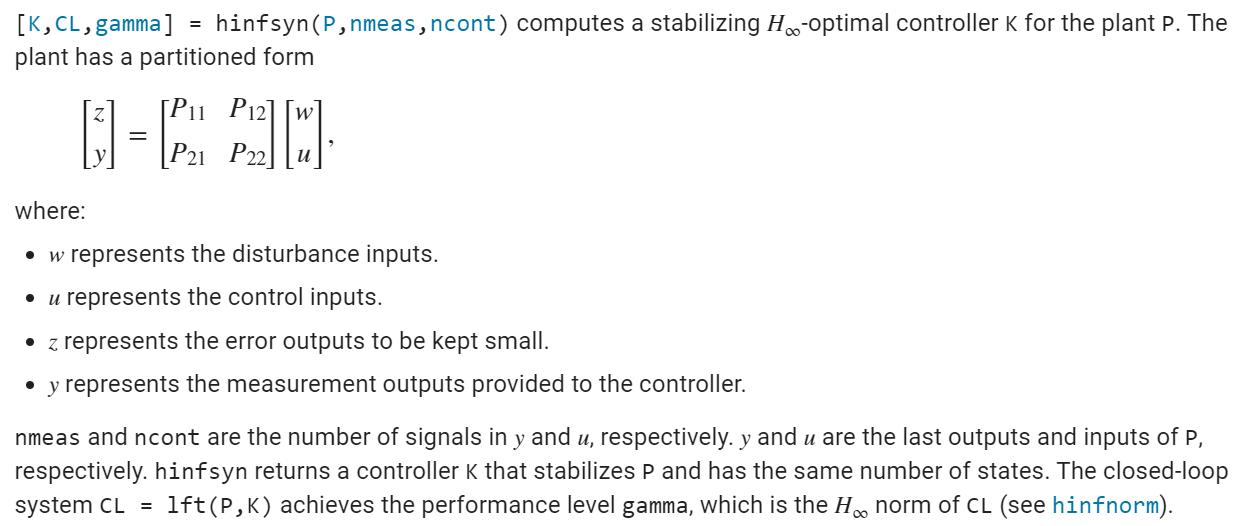

nmeas = 2;
ncont = 1;
[K,CL,gamma,info] = hinfsyn(P,nmeas,ncont)

K =
 
  A = 
               x1          x2          x3          x4          x5          x6
   x1       22.16      -159.9       177.6      -88.34      -843.6      -229.1
   x2        1837  -1.225e+04   1.336e+04       -6746  -6.442e+04   -1.75e+04
   x3      -430.6        2541       -3165        1541   1.469e+04        3989
   x4  -9.116e-08   5.979e-07  -6.644e-07      -42.77      -25.44      -12.36
   x5   8.251e-07  -5.344e-06   6.014e-06          16  -2.826e-05  -7.676e-06
   x6   3.626e-07  -2.352e-06   2.643e-06    -1.3e-06           8  -3.373e-06
 
  B = 
               u1          u2
   x1        2.47       87.01
   x2       188.6        6611
   x3      -36.12       -1255
   x4           8  -3.246e-07
   x5   8.274e-08   2.871e-06
   x6   3.636e-08   1.265e-06
 
  C = 
           x1      x2      x3      x4      x5      x6
   y1  -18.03   52.72    -130   63.72   602.1   163.3
 
  D = 
       u1  u2
   y1   0   0
 
Continuous-time state-space model.


CL =
 
  A = 
               

gamma = 0.9933

info =   hinfINFO with properties:

    gamma: 0.9933
        X: [6×6 double]
        Y: [6×6 double]
       Ku: [-18.0301 52.7175 -129.9765 63.7213 602.1292 163.3497]
       Kw: [5×6 double]
       Lx: [6×2 double]
       Lu: [0 0]
     Preg: [5×6 ss]
       AS: [3×3 ss]


#### Bode of Control Law

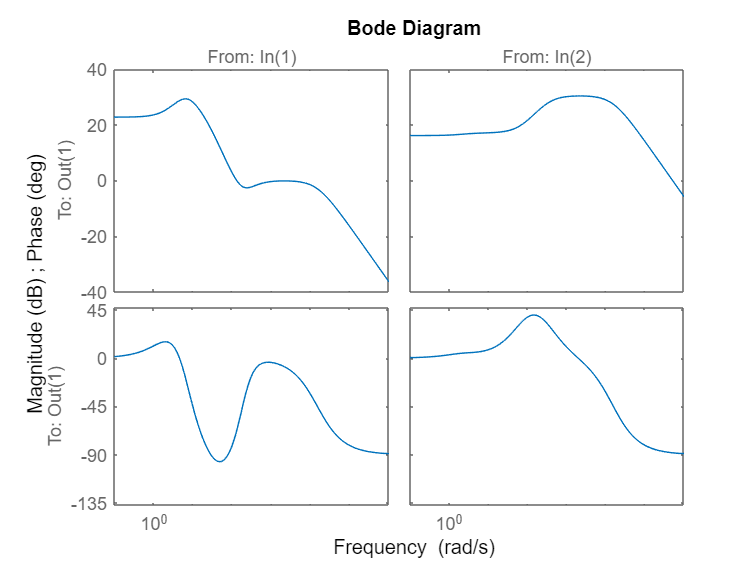

figure
bode(K)

#### Nominal Feedback System

The question is worded terriblyt... assumin negative feedback control w a normalized pilot signal still being weighted

% wcmd = W_cmd; %becouse Pilot signal is normalized...
% wcmd.InputName = 'Pilot';
% wcmd.OutputName = 'Wcmd';
% 
% K = K;
% K.InputName = {'Wcmd', 'q_sensor'};
% K.OutputName = {'delta_elev'};
% 
% G_act = G_act;
% 
% G = G;
% 
% Q_sensor = tf(-1);
% Q_sensor.InputName = 'q';
% Q_sensor.OutputName = 'q_sensor';
% 
% 
% 
% sys_feedback = connect(wcmd, K, G_act, G, Q_sensor,...
%     {'Pilot'},...
%     {'q'} ...
%     )

% sys_feedback = wcmd * feedback(K(2) * G_act * G, 1)

Feedback System Response

% step(sys_feedback)

## Final Parts

fname = matlab.desktop.editor.getActiveFilename;
export(fname, 'MECH6323_HW07.pdf')

ans = 'C:\Users\Jonas\Documents\MATLAB\Examples\R2022a\robust\HinfinityControllerSynthesisExample\MECH6323_HW07.pdf'